## Señal modulada BPSK

transmision por desplazamiento de fase binaria, consiste endesplazar la fase de una portadora senoidal de 0 a 180° con una señal binaria unipolar, es una señalizacion PM con una forma de onda digital.

es una Señal DSB-SC con una forma de onda digital polar.

La señal BPSK esta dada por S(t)


$$s\left(t\right)=A_{c\;} \;\cos \;\left\lbrack \omega_c \;t+D_p \;m\left(t\right)\;\right\rbrack$$


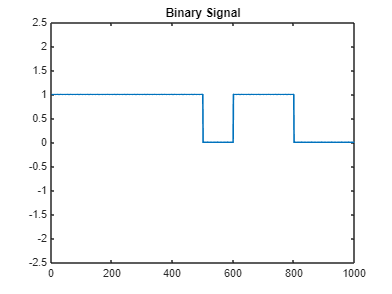

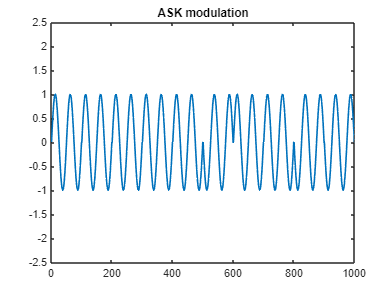

% The number of bits to send - Frame Length
N               =                 10;
time0           =            1:1:1000;
% Sampling rate - This will define the resoultion
fs              =             90;
% Generate a random bit stream
bit_stream      =   round(rand(1,N));
bpsk_signal = BPSK(bit_stream,2);

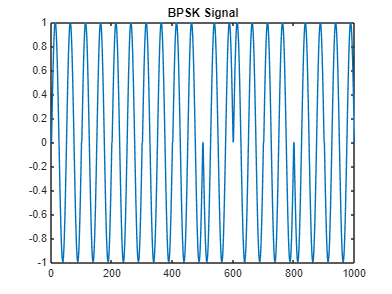

figure()
plot(time0, bpsk_signal);
title(['BPSK Signal']);

## Filtro formador de Coseno Elevado

% para recortar la señal y solo agarrar DBLSC
time_filter = 0:1:500;
time_filter_2 = 0:1:300;
filtro_rsine = rcosine(1,50);

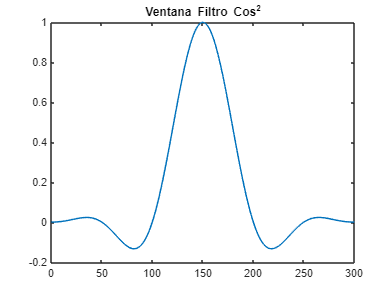

%VENTANA FILTRO
plot(time_filter_2, filtro_rsine);
title('Ventana Filtro Cos^2');

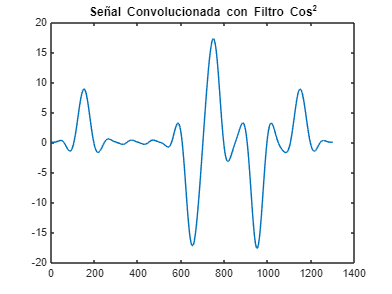

% CONVOLUTION WITH THE WINDOW
time_recover_signal = 1:1:1300;
res = conv(bpsk_signal,filtro_rsine);
plot(time_recover_signal, res);
title('Señal Convolucionada con Filtro Cos^2');

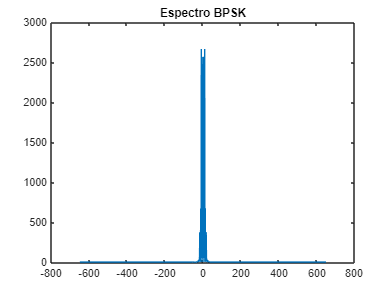

 % graficado en frecuencia
freq = -649 : 1 : 650;
bpsk_recover_sig = abs(real(ttof(res)));
plot(freq, bpsk_recover_sig);
title('Espectro BPSK');

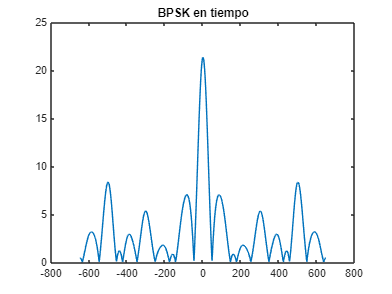

% freq to time
bpsk_signal_time = abs(real(ftot(bpsk_recover_sig)));
plot(freq, bpsk_signal_time);
title('BPSK en tiempo');

## Demodulacion BPSK

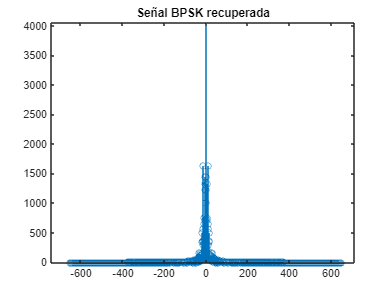

time_recover_signal_0 = -649:1:650;
stem(time_recover_signal_0, abs(real(ttof(bpsk_signal_time))));
title('Señal BPSK recuperada');

## Demodulacion Coherente BPSK

% multiplicacion y filtrado
% corrimiento de pase portadora pi/4, pi/2, 3pi/4 y pi
% desviacion frecuencia .1Hz
% observaciones





% banda acceso = .5
% 1 simbolo por segundo
g_f = 0; % espectro frecuencias filtro formador
tau = 0 ;
w = 1/tau; % ancho de banda normalizado w= 1/tau
b = w(1+aplha); %ancho de banda
alpha = 0; % ancho de banda en exceso B=W(1+ALPHA) 
f1 = 2*w-b; % diferencia entre b y 2w



% Multiplicacion señal modulada amplitud
% portadora 25 Hz

## Filtro Pasa bajas Hamming